# Visualize Vector Fields with Particles

`streamparticles` draws and animates particles within a vector field. Stream particles are usually represented by markers and can show the position and velocity of specified streamlines.

## Load Wind Vector Data

Load wind vector field and extract data from the `z = 5` plane for the 2-D animation. From the data, interpolate sets of streamlines using `interpstreamspeed `which will be used to define the particle movement.

close all
load wind
[verts,averts] = streamslice(x,y,z,u,v,w,[],[],5); 
iverts = interpstreamspeed(x,y,z,u,v,w,verts,.05);

## Basic Streamparticle Plot

Initialize the figure with a streamline plot. Create a particle animation of the provided streamline datasets by setting a number of animated particles and defining the property *Animate*'s time duration. To prevent the animation from executing as fast as possible, define a frame rate so that the particle motion can be visualized.

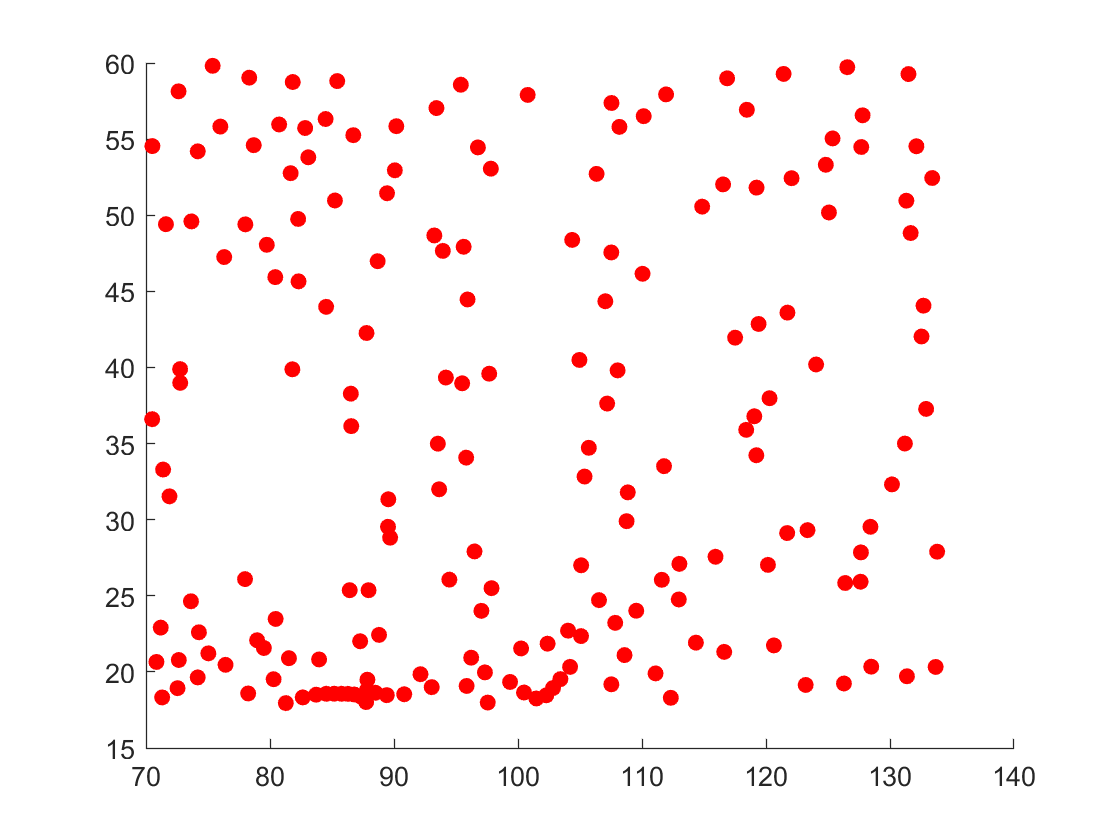

streamparticles(iverts,...                  % streamline data
    200,...                                 % number of animated particles
    "Animate",5,...                         % animation duration
    "FrameRate",40)                         % animation speed

## Customizations

### Modify Animation Properties

Create a more dense or sparse animation by adjusting the number of animated particles input. Adjust the animation duration, speed using the *Animate *and* FrameRate *properties.

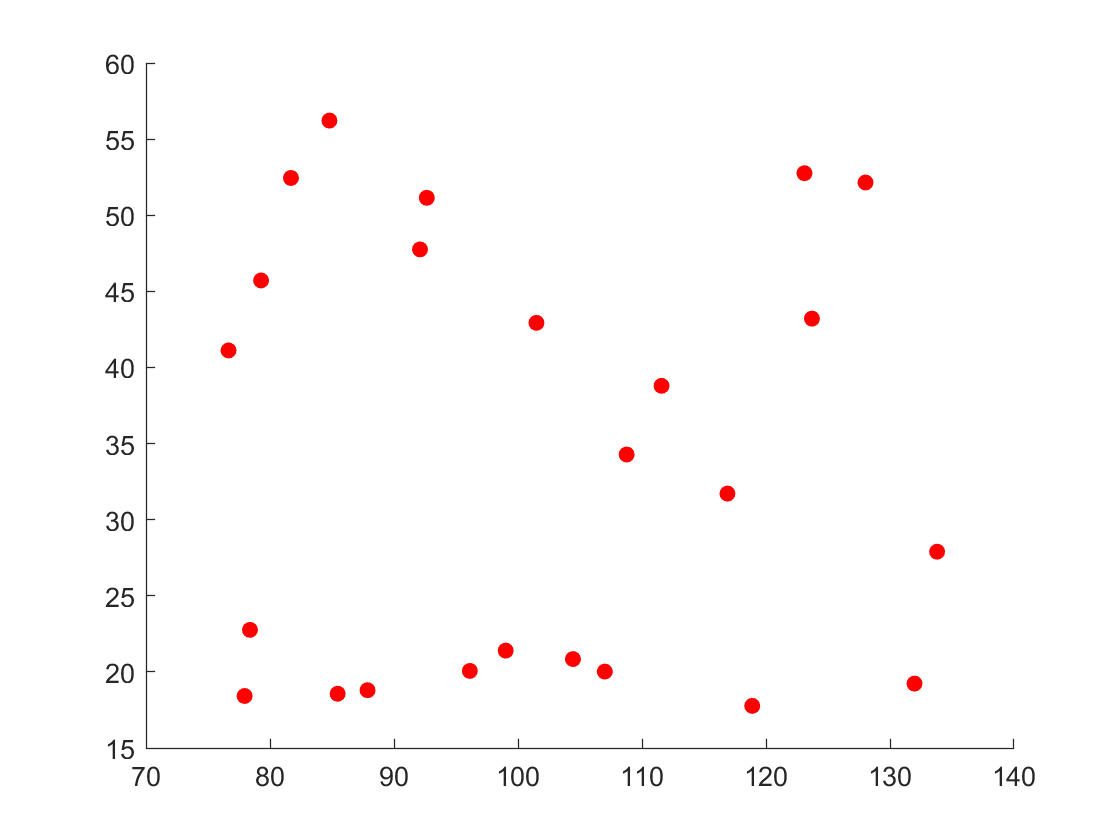

close all;
NumParticles = 25;
FrameRate = 20;
AnimateTime =2;
figure
streamparticles(iverts,...                   
    NumParticles,...                                  % set the number of animated particles
    "Animate", AnimateTime,...                        % set animation duration
    "FrameRate", FrameRate);                          % specify the animation framerate speed

### Change Particle and Plot Appearance

Change the appearance of the animated particles by modifying the *MarkerFaceColor *property to change the color of each particle and the *MarkerSize *property to change the size of each particle. The motion of the particles can be articulated by adding a streamline background using the `streamline `plotting function. To keep the animated display consistent set axis to be tight.

sp =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 10
    MarkerFaceColor: [1 0 0]
              XData: [1×190 double]
              YData: [1×190 double]
              ZData: [1×190 double]

  Show all properties


figure
sl = streamline([verts averts]);                                   % plot streamlines from the vector data

MarkerFaceColor = 'r';                      
MarkerSize = 5;
axis tight manual off;
zlim([4.9,5.1]);                       
sp = streamparticles(iverts, 200,"Animate",5,"FrameRate",40, ...
    "MarkerSize",MarkerSize,...                                    % Set the particle size
    "MarkerFaceColor",MarkerFaceColor);                            % Set the particle color

title("Particle Animation")

## **Additional Information**

### **Get All Streamparticles Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a streamparticles, uncomment the following code

% get(sp)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[streamparticles](https://www.mathworks.com/help/matlab/ref/streamparticles.html)